# Corner Detection

This example shows how to generate HDL code from a design that computes the corner metric by using Harris' technique.

## Algorithm

Corners are robust to image rotation, translation, and lighting change. They are used in many applications such as image registration and object tracking. Corners are usually identified through corner metric, which corresponds to the likelihood that the pixels locate at the corner of some objects. Peaks of corner metric identify the corners. The Harris' technique is the well known method for computing corner metric.

## MATLAB Design

The following example shows how to implement the image processing algorithm for HDL code generation.

design_name = 'mlhdlc_corner_detection';
testbench_name = 'mlhdlc_corner_detection_tb';

Let us take a look at the MATLAB® design

type(design_name);

%#codegen
function [valid, ed, xfo, yfo, cm] = mlhdlc_corner_detection(data_in)
%   Copyright 2011-2019 The MathWorks, Inc.

[~, ed, xfo, yfo] = mlhdlc_sobel(data_in);

cm = compute_corner_metric(xfo, yfo);

% compute valid signal
persistent cnt
if isempty(cnt)
  cnt = 0;
end
cnt = cnt + 1;
valid = cnt > 3*80+3 && cnt <= 80*80+3*80+3;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function bm = compute_corner_metric(gh, gv)

cmh = make_buffer_matrix_gh(gh);
cmv = make_buffer_matrix_gv(gv);
bm = compute_harris_metric(cmh, cmv);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function bm = make_buffer_matrix_gh(gh)

persistent b1 b2 b3 b4;
if isempty(b1)
    b1 = dsp.Delay('Length', 80);
    b2 = dsp.Delay('Length', 80);
    b3 = dsp.Delay('Length', 80);
    b4 = dsp.Delay('Length', 80);
end

b1p = step(b1, gh);
b2p = step(b2, b1p);
b3p = step(b3, b2p);
b4p = step(b4, b3p);

cc = [b4p b3p b2p b1p gh];

persistent h1 h2 h3

type(testbench_name);

clear mlhdlc_corner_detection;
clear mlhdlc_sobel;

%   Copyright 2011-2019 The MathWorks, Inc.

image_in = checkerboard(10);
[image_height, image_width] = size(image_in);

% Pre-allocating y for simulation performance
y_cm = zeros(image_height, image_width);
y_ed = zeros(image_height, image_width);
gradient_hori = zeros(image_height,image_width);
gradient_vert = zeros(image_height,image_width);

dataValidOut = y_cm;

idx_in = 1;
idx_out = 1;
for i=1:image_width+3
    for j=1:image_height+3
        if idx_in <= image_width * image_height
            u = image_in(idx_in);
        else
            u = 0;
        end
        idx_in = idx_in + 1;
        
        [valid, ed, gh, gv, cm] = mlhdlc_corner_detection(u);
        
        if valid
            
            y_cm(idx_out) = cm;
            y_ed(idx_out) = ed;
            gradient_hori(idx_out)   = gh;
            gradient_vert(idx_out)   = gv;
            
            idx_out = idx_out + 1;
        end
    end
end

padImage = y_cm;

## Simulate the Design

It is a good practice to simulate the design with the testbench prior to code generation to make sure there are no runtime errors.

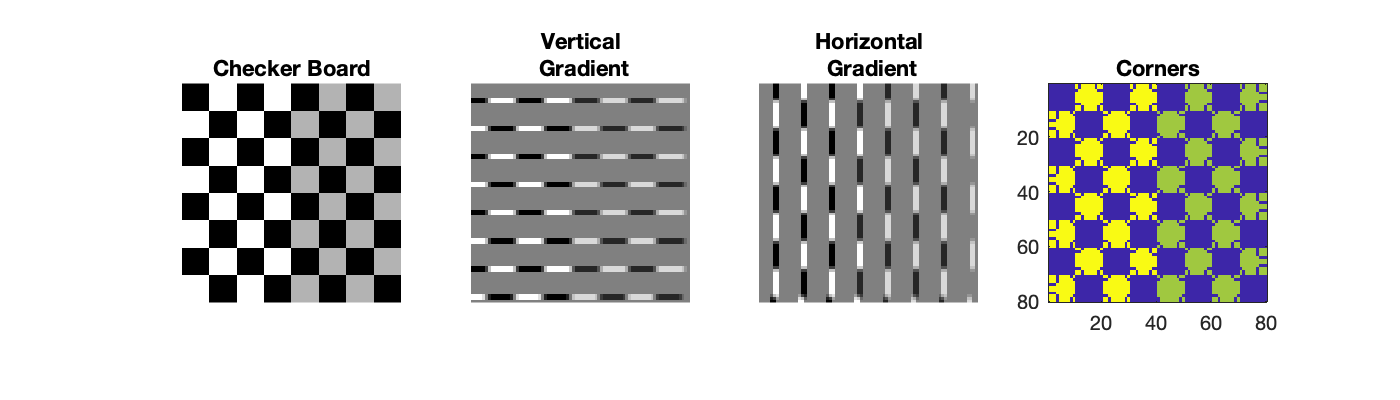

mlhdlc_corner_detection_tb

## Setup for the Example

Executing the following lines of code copies the necessary example files into a temporary folder

mlhdlc_demo_dir = fullfile(matlabroot, 'toolbox', 'hdlcoder', 'hdlcoderdemos', 'matlabhdlcoderdemos');  
mlhdlc_temp_dir = [tempdir 'mlhdlc_cdetect']; 

% create a temporary folder and copy the MATLAB files
cd(tempdir);
[~, ~, ~] = rmdir(mlhdlc_temp_dir, 's'); 
mkdir(mlhdlc_temp_dir); 
cd(mlhdlc_temp_dir);

% copy the design files to the temporary directory
copyfile(fullfile(mlhdlc_demo_dir, [design_name,'.m*']), mlhdlc_temp_dir);
copyfile(fullfile(mlhdlc_demo_dir, [testbench_name,'.m*']), mlhdlc_temp_dir);
copyfile(fullfile(mlhdlc_demo_dir, 'mlhdlc_sobel.m*'), mlhdlc_temp_dir);

## Create a New HDL Coder™ Project

Next, add the file 'mlhdlc_corner_detection.m' to the project as the MATLAB Function and 'mlhdlc_corner_detection_tb.m' as the MATLAB Test Bench.

You can refer to [Getting Started with MATLAB to HDL Workflow](mlhdlc_tutorial_sfir.html) tutorial for a more complete tutorial on creating and populating MATLAB HDL Coder projects.

## Run Fixed-Point Conversion and HDL Code Generation

Launch HDL Advisor and right click on the 'Code Generation' step and choose the option 'Run to selected task' to run all the steps from the beginning through the HDL code generation. 

Examine the generated HDL code by clicking on the hyperlinks in the Code Generation Log window.

## Clean up the Generated Files

You can run the following commands to clean up the temporary project folder.

*Copyright 2011-2015 The MathWorks, Inc.*